% importing data
load("data.mat")
head(DatiProject)

       Time        GDPC1     PCECTPI    TB3MS      GS10 
    ___________    ______    _______    ______    ______

    30-Jun-1960    3430.1    15.331       3.54    4.5033
    30-Sep-1960    3439.8    15.415       4.23    4.5833
    30-Dec-1960    3517.2    15.435     3.8733    4.4867
    30-Mar-1961    3498.2    15.515     2.9933      4.26
    30-Jun-1961    3515.4    15.574       2.36    3.8333
    30-Sep-1961    3470.3    15.642     2.3067    3.8867
    30-Dec-1961    3493.7    15.671       2.35    3.7867
    30-Mar-1962      3553     15.67     2.3033      3.79



% section 1
log_GDP = log(DatiProject.GDPC1)

log_GDP =     8.1403
    8.1432
    8.1654
    8.1600
    8.1649
    8.1520
    8.1587
    8.1756
    8.1946
    8.2140


log_GDP

log_GDP =     8.1403
    8.1432
    8.1654
    8.1600
    8.1649
    8.1520
    8.1587
    8.1756
    8.1946
    8.2140


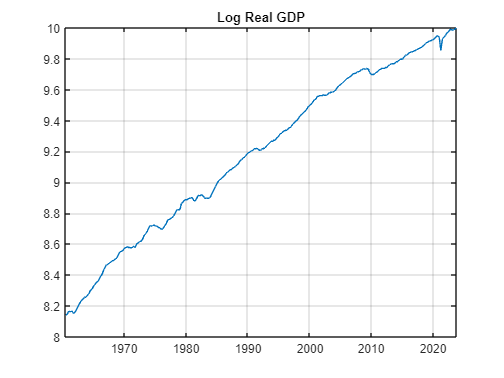

plot(DatiProject.Time,log_GDP)
title("Log Real GDP")
grid on
hold off

delta_log_GDP = diff(log_GDP)

delta_log_GDP =     0.0028
    0.0222
   -0.0054
    0.0049
   -0.0129
    0.0067
    0.0168
    0.0190
    0.0194
    0.0177


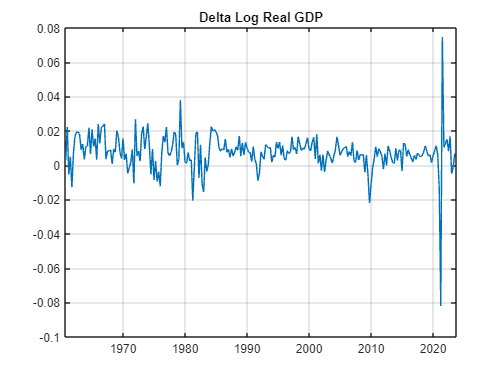

plot(DatiProject.Time(2:end),delta_log_GDP)
title("Delta Log Real GDP")
grid on
hold off

log_PCE = log(DatiProject.PCECTPI)

log_PCE =     2.7299
    2.7353
    2.7366
    2.7418
    2.7456
    2.7500
    2.7518
    2.7517
    2.7553
    2.7564


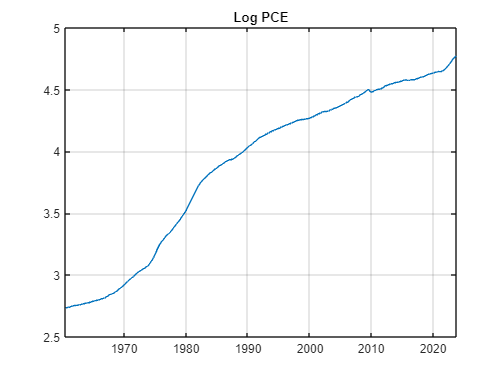

plot(DatiProject.Time,log_PCE)
title("Log PCE")
grid on
hold off

inflation = diff(log_PCE)

inflation =     0.0055
    0.0013
    0.0052
    0.0038
    0.0044
    0.0019
   -0.0001
    0.0036
    0.0011
    0.0043


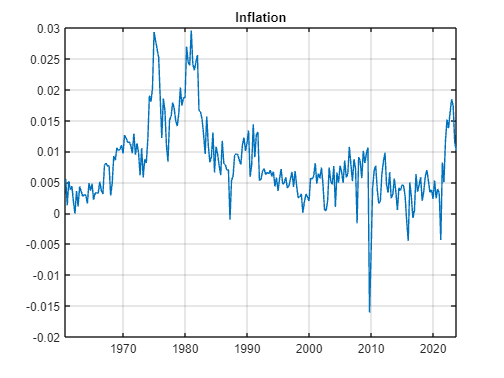

plot(DatiProject.Time(2:end),inflation)
title("Inflation")
grid on
hold off

Tspread = DatiProject.GS10-DatiProject.TB3MS

Tspread =     0.9633
    0.3533
    0.6134
    1.2667
    1.4733
    1.5800
    1.4367
    1.4867
    1.6767
    1.5133


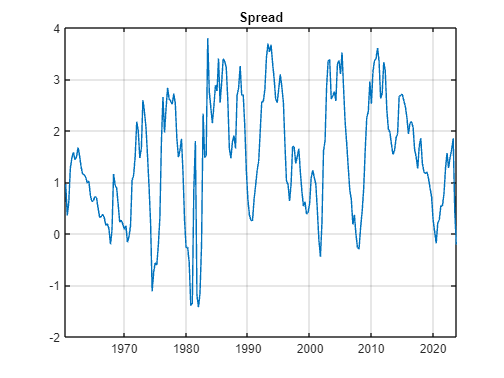

plot(DatiProject.Time,Tspread)
title("Spread")
grid on
hold off

% subsetting
DatiProject = DatiProject(1:235,:)

DatiProject = 235×5 table
       Time        GDPC1     PCECTPI    TB3MS      GS10 
    ___________    ______    _______    ______    ______

    30-Jun-1960    3430.1    15.331       3.54    4.5033
    30-Sep-1960    3439.8    15.415       4.23    4.5833
    30-Dec-1960    3517.2    15.435     3.8733    4.4867
    30-Mar-1961    3498.2    15.515     2.9933      4.26
    30-Jun-1961    3515.4    15.574       2.36    3.8333
    30-Sep-1961    3470.3    15.642     2.3067    3.8867
    30-Dec-1961    3493.7    15.671       2.35    3.7867
    30-Mar-1962      3553     15.67     2.3033      3.79
    30-Jun-1962    3621.3    15.726     2.3033      3.98
    30-Sep-1962    3692.3    15.743       2.46    3.9733
    30-Dec-1962    3758.1    15.811     2.7233    4.0167
    30-Mar-1963    3792.1    15.867     2.7167    3.8733
    3

% section 2
sample_delta_log_GDP = delta_log_GDP(1:100)

sample_delta_log_GDP =     0.0028
    0.0222
   -0.0054
    0.0049
   -0.0129
    0.0067
    0.0168
    0.0190
    0.0194
    0.0177


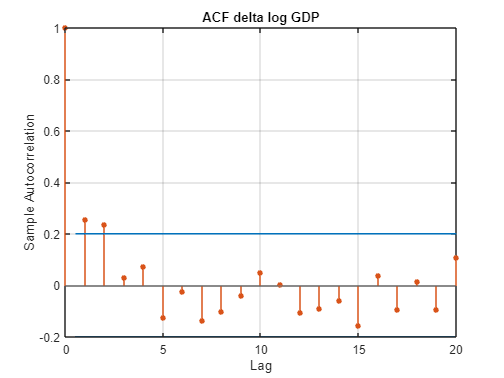

autocorr(sample_delta_log_GDP)
hold on
title('ACF delta log GDP')
hold off

sample_inflation = inflation(1:100)

sample_inflation =     0.0055
    0.0013
    0.0052
    0.0038
    0.0044
    0.0019
   -0.0001
    0.0036
    0.0011
    0.0043


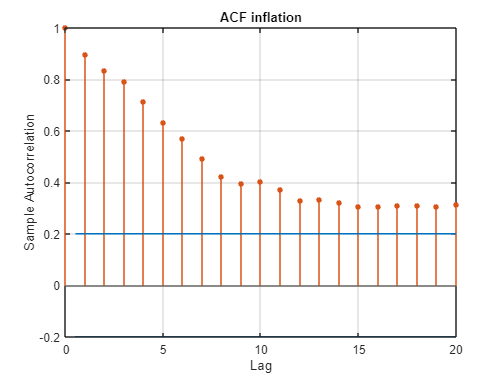

autocorr(sample_inflation)
hold on
title('ACF inflation')
hold off

sample_Tspread = Tspread(2:101)

sample_Tspread =     0.3533
    0.6134
    1.2667
    1.4733
    1.5800
    1.4367
    1.4867
    1.6767
    1.5133
    1.2934


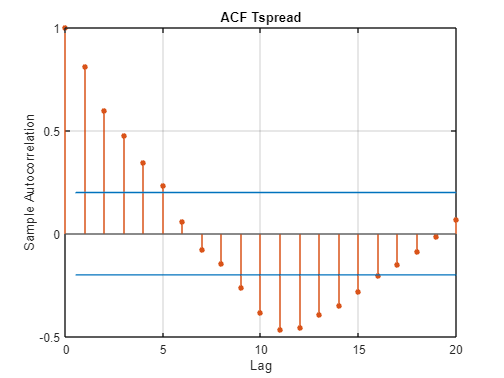

autocorr(sample_Tspread)
hold on
title('ACF Tspread')
hold off

% VAR(p)
var_matrix = [delta_log_GDP inflation Tspread(2:end)]

var_matrix =     0.0028    0.0055    0.3533
    0.0222    0.0013    0.6134
   -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934


h = 1

h = 1

FORE_VARp = NaN(134,h,3)

FORE_VARp = FORE_VARp(:,:,1) =

   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


FORE_VARp(:,:,2) =

   NaN
 

p_mins = NaN(134,1)

p_mins =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


for j = 1:134
    roll = var_matrix(j:99+j,:)
    aic_var = NaN(4,1)
    for pp = 1:4
        tmpm = estimate(varm(3,pp),roll,Display='off')
        tmps = summarize(tmpm)
        aic_var(pp,1) = tmps.AIC
    end
    [p_min] = find(aic_var==min(aic_var,[],'all'))
    p_mins(j,:) = p_min
    FORE_VARp(j,h,:) = forecast((estimate(varm(3,p_min),roll,Display='off')),h,roll)
end

roll =     0.0028    0.0055    0.3533
    0.0222    0.0013    0.6134
   -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934


aic_var =    NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00953104 0.00134314 0.374669]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.9352
                       AIC: -1.2879e+03
                       BIC: -1.2567e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2879
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00783385 0.00144302 0.426081]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 661.0929
                       AIC: -1.2802e+03
                       BIC: -1.2259e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2879
   -1.2802
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00963043 0.00122557 0.428192]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 664.5192
                       AIC: -1.2690e+03
                       BIC: -1.1918e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2879
   -1.2802
   -1.2690
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0107636 -0.000231226 0.391708]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 677.3898
                       AIC: -1.2768e+03
                       BIC: -1.1768e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2879
   -1.2802
   -1.2690
   -1.2768


p_min = 1

p_mins =      1
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll =     0.0222    0.0013    0.6134
   -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566


aic_var =    NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00886862 0.00157028 0.376156]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.8443
                       AIC: -1.2917e+03
                       BIC: -1.2605e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2917
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00846332 0.00139913 0.406942]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 661.2995
                       AIC: -1.2806e+03
                       BIC: -1.2263e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2917
   -1.2806
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0101309 0.00130758 0.398276]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 663.4043
                       AIC: -1.2668e+03
                       BIC: -1.1896e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2917
   -1.2806
   -1.2668
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0122527 -0.000183298 0.362378]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 677.5875
                       AIC: -1.2772e+03
                       BIC: -1.1772e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2917
   -1.2806
   -1.2668
   -1.2772


p_min = 1

p_mins =      1
     1
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll =    -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500


aic_var =    NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00946616 0.00153216 0.359294]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.0362
                       AIC: -1.2921e+03
                       BIC: -1.2609e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2921
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00867438 0.00143329 0.399459]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 658.9669
                       AIC: -1.2759e+03
                       BIC: -1.2216e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2921
   -1.2759
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0112774 0.00129141 0.389903]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 665.8181
                       AIC: -1.2716e+03
                       BIC: -1.1944e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2921
   -1.2759
   -1.2716
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0130347 0.000174231 0.370342]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 678.9537
                       AIC: -1.2799e+03
                       BIC: -1.1799e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2921
   -1.2759
   -1.2716
   -1.2799


p_min = 1

p_mins =      1
     1
     1
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll =     0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900


aic_var =    NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00979124 0.00168281 0.353057]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.7494
                       AIC: -1.2915e+03
                       BIC: -1.2604e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2915
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0101054 0.00147435 0.40235]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 662.6554
                       AIC: -1.2833e+03
                       BIC: -1.2290e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2915
   -1.2833
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0120009 0.00159382 0.427855]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 666.7562
                       AIC: -1.2735e+03
                       BIC: -1.1963e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2915
   -1.2833
   -1.2735
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.012886 0.000547633 0.421605]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 678.4664
                       AIC: -1.2789e+03
                       BIC: -1.1789e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2915
   -1.2833
   -1.2735
   -1.2789


p_min = 1

p_mins =      1
     1
     1
     1
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll =    -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866


aic_var =    NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0107894 0.00169079 0.350619]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 661.9338
                       AIC: -1.2999e+03
                       BIC: -1.2687e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2999
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0105836 0.00169888 0.423445]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 663.4571
                       AIC: -1.2849e+03
                       BIC: -1.2306e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2999
   -1.2849
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.01173 0.00202359 0.467111]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 668.2298
                       AIC: -1.2765e+03
                       BIC: -1.1992e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2999
   -1.2849
   -1.2765
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0129142 0.000453352 0.420278]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 678.2898
                       AIC: -1.2786e+03
                       BIC: -1.1786e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.2999
   -1.2849
   -1.2765
   -1.2786


p_min = 1

p_mins =      1
     1
     1
     1
     1
   NaN
   NaN
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll =     0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233


aic_var =    NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0111169 0.00189153 0.380092]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 662.0290
                       AIC: -1.3001e+03
                       BIC: -1.2689e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 1.0e+03 *

   -1.3001
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0103474 0.00205971 0.444454]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 663.6395
                       AIC: -1.2853e+03
                       BIC: -1.2310e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3001
   -1.2853
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0115799 0.00193134 0.475486]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 666.5689
                       AIC: -1.2731e+03
                       BIC: -1.1959e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3001
   -1.2853
   -1.2731
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0124317 0.000333034 0.414901]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 676.9733
                       AIC: -1.2759e+03
                       BIC: -1.1759e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3001
   -1.2853
   -1.2731
   -1.2759


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
   NaN
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0109048 0.00204448 0.36998]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 661.5655
                       AIC: -1.2991e+03
                       BIC: -1.2680e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2991
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0100394 0.00196557 0.430962]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 662.7301
                       AIC: -1.2835e+03
                       BIC: -1.2292e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2991
   -1.2835
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0112412 0.00199299 0.453249]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 665.0527
                       AIC: -1.2701e+03
                       BIC: -1.1929e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2991
   -1.2835
   -1.2701
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0120751 0.000174156 0.380359]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 674.8552
                       AIC: -1.2717e+03
                       BIC: -1.1717e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2991
   -1.2835
   -1.2701
   -1.2717


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
   NaN
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0106039 0.00176689 0.356442]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.0416
                       AIC: -1.2921e+03
                       BIC: -1.2609e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2921
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00953031 0.00171864 0.42771]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 658.1435
                       AIC: -1.2743e+03
                       BIC: -1.2200e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2921
   -1.2743
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0108581 0.00157691 0.435467]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 658.8153
                       AIC: -1.2576e+03
                       BIC: -1.1804e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2921
   -1.2743
   -1.2576
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0115221 -0.000367173 0.352821]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 666.7179
                       AIC: -1.2554e+03
                       BIC: -1.1554e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2921
   -1.2743
   -1.2576
   -1.2554


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
   NaN
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0102144 0.0021391 0.37107]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.4608
                       AIC: -1.2909e+03
                       BIC: -1.2598e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2909
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00922309 0.00185999 0.435503]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 657.5193
                       AIC: -1.2730e+03
                       BIC: -1.2188e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2909
   -1.2730
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0106429 0.00177799 0.409834]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 658.3502
                       AIC: -1.2567e+03
                       BIC: -1.1795e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2909
   -1.2730
   -1.2567
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0110691 -0.000173664 0.321206]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 666.2830
                       AIC: -1.2546e+03
                       BIC: -1.1546e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2909
   -1.2730
   -1.2567
   -1.2546


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
   NaN


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0177    0.0043    1.2934
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00994383 0.00208634 0.379366]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.2903
                       AIC: -1.2906e+03
                       BIC: -1.2594e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2906
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00897034 0.00197273 0.448236]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 657.2572
                       AIC: -1.2725e+03
                       BIC: -1.2182e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2906
   -1.2725
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0104111 0.00185735 0.405583]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 658.2332
                       AIC: -1.2565e+03
                       BIC: -1.1792e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2906
   -1.2725
   -1.2565
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0109566 -7.65127e-06 0.324108]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 666.8488
                       AIC: -1.2557e+03
                       BIC: -1.1557e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2906
   -1.2725
   -1.2565
   -1.2557


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0090    0.0035    1.1566
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00991542 0.00221087 0.374571]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.9501
                       AIC: -1.2899e+03
                       BIC: -1.2588e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00882215 0.00214922 0.441639]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 656.7203
                       AIC: -1.2714e+03
                       BIC: -1.2172e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
   -1.2714
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0103035 0.00216338 0.419812]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 657.5777
                       AIC: -1.2552e+03
                       BIC: -1.1779e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
   -1.2714
   -1.2552
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0106992 0.000374425 0.329989]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 665.7739
                       AIC: -1.2535e+03
                       BIC: -1.1535e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
   -1.2714
   -1.2552
   -1.2535


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0122    0.0027    1.1500
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0099091 0.00229993 0.394254]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.8089
                       AIC: -1.2876e+03
                       BIC: -1.2565e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00922053 0.00221612 0.485912]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.8323
                       AIC: -1.2697e+03
                       BIC: -1.2154e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
   -1.2697
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0103565 0.00227243 0.480134]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.8405
                       AIC: -1.2517e+03
                       BIC: -1.1744e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
   -1.2697
   -1.2517
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0105334 0.00065204 0.439697]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.6057
                       AIC: -1.2472e+03
                       BIC: -1.1472e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
   -1.2697
   -1.2517
   -1.2472


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0033    0.0030    1.0900
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0103175 0.00234933 0.397833]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.3253
                       AIC: -1.2887e+03
                       BIC: -1.2575e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2887
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00929895 0.00229402 0.499063]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.8979
                       AIC: -1.2698e+03
                       BIC: -1.2155e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2887
   -1.2698
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0103694 0.00248798 0.494959]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 656.2192
                       AIC: -1.2524e+03
                       BIC: -1.1752e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2887
   -1.2698
   -1.2524
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00981332 0.000568582 0.477776]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.9492
                       AIC: -1.2479e+03
                       BIC: -1.1479e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2887
   -1.2698
   -1.2524
   -1.2479


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0109    0.0029    0.9866
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0103526 0.00244073 0.413548]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.8770
                       AIC: -1.2878e+03
                       BIC: -1.2566e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2878
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00933031 0.00249368 0.507763]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.7183
                       AIC: -1.2694e+03
                       BIC: -1.2152e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2878
   -1.2694
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00969068 0.00238401 0.526685]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.7234
                       AIC: -1.2514e+03
                       BIC: -1.1742e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2878
   -1.2694
   -1.2514
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0102232 0.000607333 0.492851]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.5846
                       AIC: -1.2452e+03
                       BIC: -1.1452e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2878
   -1.2694
   -1.2514
   -1.2452


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0112    0.0016    1.0233
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0105595 0.002591 0.420244]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.5248
                       AIC: -1.2870e+03
                       BIC: -1.2559e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2870
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00890425 0.0024173 0.537539]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.7397
                       AIC: -1.2695e+03
                       BIC: -1.2152e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2870
   -1.2695
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0101221 0.00249011 0.532317]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.3929
                       AIC: -1.2508e+03
                       BIC: -1.1735e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2870
   -1.2695
   -1.2508
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00982349 0.000563497 0.503443]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.5379
                       AIC: -1.2451e+03
                       BIC: -1.1451e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2870
   -1.2695
   -1.2508
   -1.2451


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0218    0.0049    0.7400
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0100844 0.00255737 0.444066]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.7047
                       AIC: -1.2874e+03
                       BIC: -1.2563e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00912958 0.00252461 0.54398]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.6590
                       AIC: -1.2693e+03
                       BIC: -1.2150e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
   -1.2693
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00958505 0.00250673 0.534853]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.3774
                       AIC: -1.2508e+03
                       BIC: -1.1735e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
   -1.2693
   -1.2508
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00978922 0.000742231 0.502328]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.7898
                       AIC: -1.2456e+03
                       BIC: -1.1456e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
   -1.2693
   -1.2508
   -1.2456


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0065    0.0037    0.6233
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.01033 0.00262031 0.451441]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.6859
                       AIC: -1.2874e+03
                       BIC: -1.2562e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00865227 0.00254946 0.546983]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.5851
                       AIC: -1.2692e+03
                       BIC: -1.2149e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
   -1.2692
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00956537 0.00264479 0.536909]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.3863
                       AIC: -1.2508e+03
                       BIC: -1.1735e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
   -1.2692
   -1.2508
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.009663 0.000825308 0.507289]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.2239
                       AIC: -1.2444e+03
                       BIC: -1.1444e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2874
   -1.2692
   -1.2508
   -1.2444


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0209    0.0048    0.6500
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00971136 0.00265628 0.461596]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.4720
                       AIC: -1.2869e+03
                       BIC: -1.2558e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00861704 0.00275664 0.549615]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.7091
                       AIC: -1.2694e+03
                       BIC: -1.2151e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
   -1.2694
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0093707 0.0026553 0.531364]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.7336
                       AIC: -1.2495e+03
                       BIC: -1.1722e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
   -1.2694
   -1.2495
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0100823 0.000794497 0.521336]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 660.4017
                       AIC: -1.2428e+03
                       BIC: -1.1428e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
   -1.2694
   -1.2495
   -1.2428


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0108    0.0022    0.7233
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00975792 0.00282305 0.4521]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.0105
                       AIC: -1.2880e+03
                       BIC: -1.2569e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2880
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00838663 0.00279491 0.549993]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.4957
                       AIC: -1.2690e+03
                       BIC: -1.2147e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2880
   -1.2690
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00973432 0.00272778 0.533521]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.7387
                       AIC: -1.2495e+03
                       BIC: -1.1722e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2880
   -1.2690
   -1.2495
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00903416 0.000965377 0.528756]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.7485
                       AIC: -1.2455e+03
                       BIC: -1.1455e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2880
   -1.2690
   -1.2495
   -1.2455


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0155    0.0033    0.6966
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00950286 0.0029248 0.456372]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.9554
                       AIC: -1.2879e+03
                       BIC: -1.2568e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00885021 0.00293522 0.566753]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 656.0952
                       AIC: -1.2702e+03
                       BIC: -1.2159e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
   -1.2702
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00855836 0.0028967 0.546509]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.7924
                       AIC: -1.2516e+03
                       BIC: -1.1743e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
   -1.2702
   -1.2516
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.008787 0.000991277 0.524277]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.4540
                       AIC: -1.2449e+03
                       BIC: -1.1449e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
   -1.2702
   -1.2516
   -1.2449


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0031    0.0033    0.4900
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0100039 0.00286744 0.468133]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 653.9037
                       AIC: -1.2838e+03
                       BIC: -1.2527e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2838
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00778344 0.00288153 0.594654]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 654.7443
                       AIC: -1.2675e+03
                       BIC: -1.2132e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2838
   -1.2675
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00840629 0.00273507 0.553004]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 652.7347
                       AIC: -1.2455e+03
                       BIC: -1.1682e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2838
   -1.2675
   -1.2455
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00791568 0.000917563 0.506016]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 659.6798
                       AIC: -1.2414e+03
                       BIC: -1.1414e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2838
   -1.2675
   -1.2455
   -1.2414


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0239    0.0032    0.3133
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00845845 0.00304872 0.489783]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.1989
                       AIC: -1.2864e+03
                       BIC: -1.2553e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2864
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00731713 0.00288556 0.591566]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 654.3194
                       AIC: -1.2666e+03
                       BIC: -1.2124e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2864
   -1.2666
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0071842 0.00285459 0.521707]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.5087
                       AIC: -1.2470e+03
                       BIC: -1.1698e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2864
   -1.2666
   -1.2470
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00655086 0.000852177 0.493469]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 660.6712
                       AIC: -1.2433e+03
                       BIC: -1.1433e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2864
   -1.2666
   -1.2470
   -1.2433


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0126    0.0051    0.3334
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00867484 0.00338464 0.497835]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 653.9696
                       AIC: -1.2839e+03
                       BIC: -1.2528e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2839
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00695571 0.00344503 0.602402]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 654.3735
                       AIC: -1.2667e+03
                       BIC: -1.2125e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2839
   -1.2667
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00685001 0.00328794 0.520513]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.3180
                       AIC: -1.2486e+03
                       BIC: -1.1714e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2839
   -1.2667
   -1.2486
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00626215 0.00116989 0.493041]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.0537
                       AIC: -1.2441e+03
                       BIC: -1.1441e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2839
   -1.2667
   -1.2486
   -1.2441


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0220    0.0037    0.3800
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00791402 0.00355611 0.508827]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 654.4440
                       AIC: -1.2849e+03
                       BIC: -1.2537e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2849
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0060838 0.00344581 0.624733]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.6823
                       AIC: -1.2694e+03
                       BIC: -1.2151e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2849
   -1.2694
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00587456 0.00294378 0.543966]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.6112
                       AIC: -1.2512e+03
                       BIC: -1.1740e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2849
   -1.2694
   -1.2512
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00636289 0.000981951 0.493722]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 660.6713
                       AIC: -1.2433e+03
                       BIC: -1.1433e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2849
   -1.2694
   -1.2512
   -1.2433


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0228    0.0031    0.3066
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00696375 0.00383979 0.523201]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.4293
                       AIC: -1.2869e+03
                       BIC: -1.2557e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00504827 0.00337282 0.642094]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 657.4169
                       AIC: -1.2728e+03
                       BIC: -1.2185e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
   -1.2728
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00566803 0.00309519 0.551539]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.8940
                       AIC: -1.2498e+03
                       BIC: -1.1725e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
   -1.2728
   -1.2498
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00578601 0.00119983 0.524695]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 659.8291
                       AIC: -1.2417e+03
                       BIC: -1.1416e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2869
   -1.2728
   -1.2498
   -1.2417


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0240    0.0077    0.1600
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00573363 0.00374334 0.541566]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.1113
                       AIC: -1.2862e+03
                       BIC: -1.2551e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2862
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00455437 0.00342356 0.644127]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.5337
                       AIC: -1.2691e+03
                       BIC: -1.2148e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2862
   -1.2691
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00513311 0.00313623 0.554165]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.1396
                       AIC: -1.2463e+03
                       BIC: -1.1690e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2862
   -1.2691
   -1.2463
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00487638 0.00143039 0.555495]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 659.0735
                       AIC: -1.2401e+03
                       BIC: -1.1401e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2862
   -1.2691
   -1.2463
   -1.2401


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0034    0.0081    0.1933
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00567442 0.00361155 0.552953]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 652.4809
                       AIC: -1.2810e+03
                       BIC: -1.2498e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2810
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00399076 0.00322868 0.673944]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 652.6280
                       AIC: -1.2633e+03
                       BIC: -1.2090e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2810
   -1.2633
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00432809 0.00287747 0.612994]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 650.9932
                       AIC: -1.2420e+03
                       BIC: -1.1647e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2810
   -1.2633
   -1.2420
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00417784 0.00184727 0.569779]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.1281
                       AIC: -1.2443e+03
                       BIC: -1.1442e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2810
   -1.2633
   -1.2420
   -1.2443


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0084    0.0076    0.0967
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00542658 0.00370681 0.601161]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 652.8563
                       AIC: -1.2817e+03
                       BIC: -1.2506e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2817
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00374073 0.00325212 0.73604]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 653.3105
                       AIC: -1.2646e+03
                       BIC: -1.2103e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2817
   -1.2646
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00398442 0.00340142 0.615162]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.2927
                       AIC: -1.2466e+03
                       BIC: -1.1693e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2817
   -1.2646
   -1.2466
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00442488 0.00173593 0.517978]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.1178
                       AIC: -1.2442e+03
                       BIC: -1.1442e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2817
   -1.2646
   -1.2466
   -1.2442


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0082    0.0077   -0.2067
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00507605 0.0038466 0.643606]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 653.2283
                       AIC: -1.2825e+03
                       BIC: -1.2513e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2825
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00311463 0.00385028 0.740995]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.7393
                       AIC: -1.2695e+03
                       BIC: -1.2152e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2825
   -1.2695
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00398407 0.00358158 0.539664]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.5335
                       AIC: -1.2471e+03
                       BIC: -1.1698e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2825
   -1.2695
   -1.2471
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0032085 0.00131465 0.569985]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.1540
                       AIC: -1.2463e+03
                       BIC: -1.1463e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2825
   -1.2695
   -1.2471
   -1.2463


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0088    0.0029    0.0700
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00459814 0.00438531 0.659868]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.5326
                       AIC: -1.2871e+03
                       BIC: -1.2559e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2871
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00310286 0.00406447 0.700132]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 655.5782
                       AIC: -1.2692e+03
                       BIC: -1.2149e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2871
   -1.2692
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00281643 0.00328293 0.619724]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.6363
                       AIC: -1.2473e+03
                       BIC: -1.1700e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2871
   -1.2692
   -1.2473
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00248119 0.00159194 0.586977]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 660.7566
                       AIC: -1.2435e+03
                       BIC: -1.1435e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2871
   -1.2692
   -1.2473
   -1.2435


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0006    0.0048    1.1600
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0051798 0.0045641 0.603859]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.6396
                       AIC: -1.2873e+03
                       BIC: -1.2561e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2873
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00242552 0.00368129 0.78335]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 656.1153
                       AIC: -1.2702e+03
                       BIC: -1.2159e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2873
   -1.2702
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00278777 0.00330142 0.624081]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.1985
                       AIC: -1.2464e+03
                       BIC: -1.1692e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2873
   -1.2702
   -1.2464
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.000997503 0.00156361 0.665175]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.1387
                       AIC: -1.2463e+03
                       BIC: -1.1463e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2873
   -1.2702
   -1.2464
   -1.2463


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0094    0.0093    0.9467
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00499533 0.0043873 0.646607]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.7842
                       AIC: -1.2876e+03
                       BIC: -1.2564e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00232788 0.00378981 0.808898]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 656.1130
                       AIC: -1.2702e+03
                       BIC: -1.2159e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
   -1.2702
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00154659 0.00319159 0.669653]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.5032
                       AIC: -1.2490e+03
                       BIC: -1.1718e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
   -1.2702
   -1.2490
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [7.90589e-05 0.00161018 0.695729]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.6123
                       AIC: -1.2472e+03
                       BIC: -1.1472e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2876
   -1.2702
   -1.2490
   -1.2472


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0075    0.0086    0.8900
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00501861 0.00448478 0.655521]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 655.9306
                       AIC: -1.2879e+03
                       BIC: -1.2567e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00154015 0.00375496 0.840831]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 657.5737
                       AIC: -1.2731e+03
                       BIC: -1.2189e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
   -1.2731
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.000878424 0.00329517 0.691105]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.4066
                       AIC: -1.2508e+03
                       BIC: -1.1736e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
   -1.2731
   -1.2508
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000228275 0.00168652 0.697183]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.4932
                       AIC: -1.2470e+03
                       BIC: -1.1470e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2879
   -1.2731
   -1.2508
   -1.2470


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0202    0.0106    0.5600
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0042818 0.00446437 0.685903]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.0842
                       AIC: -1.2902e+03
                       BIC: -1.2590e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2902
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0010004 0.00384982 0.863827]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 658.4009
                       AIC: -1.2748e+03
                       BIC: -1.2205e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2902
   -1.2748
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.000760764 0.00338253 0.682145]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.1136
                       AIC: -1.2502e+03
                       BIC: -1.1730e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2902
   -1.2748
   -1.2502
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000374969 0.00164096 0.721502]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.1640
                       AIC: -1.2463e+03
                       BIC: -1.1463e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2902
   -1.2748
   -1.2502
   -1.2463


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0166    0.0102    0.2233
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00403452 0.00455191 0.70128]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.9635
                       AIC: -1.2899e+03
                       BIC: -1.2588e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.000975281 0.00393499 0.86838]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 657.2936
                       AIC: -1.2726e+03
                       BIC: -1.2183e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
   -1.2726
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.000950956 0.00342086 0.702131]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.8787
                       AIC: -1.2478e+03
                       BIC: -1.1705e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
   -1.2726
   -1.2478
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00099535 0.0019096 0.751309]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 663.3949
                       AIC: -1.2488e+03
                       BIC: -1.1488e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2899
   -1.2726
   -1.2478
   -1.2488


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0077    0.0103    0.2633
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00386263 0.00467734 0.704845]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.8631
                       AIC: -1.2897e+03
                       BIC: -1.2586e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2897
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.000897733 0.00397471 0.892638]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 656.8493
                       AIC: -1.2717e+03
                       BIC: -1.2174e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2897
   -1.2717
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [-4.51305e-05 0.0036038 0.731683]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.0423
                       AIC: -1.2501e+03
                       BIC: -1.1728e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2897
   -1.2717
   -1.2501
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000989669 0.00195669 0.775083]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.6122
                       AIC: -1.2472e+03
                       BIC: -1.1472e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2897
   -1.2717
   -1.2501
   -1.2472


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0039    0.0110    0.1833
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00382319 0.00471317 0.724865]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.3967
                       AIC: -1.2888e+03
                       BIC: -1.2577e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2888
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.000276583 0.00412194 0.925724]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 657.9628
                       AIC: -1.2739e+03
                       BIC: -1.2196e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2888
   -1.2739
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [-8.77422e-05 0.0035186 0.751542]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 653.9486
                       AIC: -1.2479e+03
                       BIC: -1.1707e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2888
   -1.2739
   -1.2479
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00158398 0.00201864 0.838141]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 661.9943
                       AIC: -1.2460e+03
                       BIC: -1.1460e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2888
   -1.2739
   -1.2479
   -1.2460


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0155    0.0096    0.0834
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00319927 0.00492583 0.750358]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.0962
                       AIC: -1.2922e+03
                       BIC: -1.2611e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2922
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.00022439 0.00408172 0.954357]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 658.0945
                       AIC: -1.2742e+03
                       BIC: -1.2199e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2922
   -1.2742
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [-0.000435678 0.00360019 0.796123]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.4932
                       AIC: -1.2490e+03
                       BIC: -1.1717e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2922
   -1.2742
   -1.2490
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000974203 0.00210144 0.873908]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.4405
                       AIC: -1.2469e+03
                       BIC: -1.1469e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2922
   -1.2742
   -1.2490
   -1.2469


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0030    0.0127    0.1566
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00332888 0.00479961 0.775295]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.6490
                       AIC: -1.2913e+03
                       BIC: -1.2602e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2913
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.000634853 0.00400359 1.01958]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 658.4135
                       AIC: -1.2748e+03
                       BIC: -1.2205e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2913
   -1.2748
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.000233405 0.0036681 0.824779]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.6568
                       AIC: -1.2493e+03
                       BIC: -1.1721e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2913
   -1.2748
   -1.2493
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000964397 0.0023157 0.934045]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.8834
                       AIC: -1.2478e+03
                       BIC: -1.1478e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2913
   -1.2748
   -1.2493
   -1.2478


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0066    0.0122   -0.1666
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00321127 0.00493041 0.828139]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.3392
                       AIC: -1.2927e+03
                       BIC: -1.2615e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2927
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [5.76831e-05 0.00424283 1.06245]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 659.1549
                       AIC: -1.2763e+03
                       BIC: -1.2220e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2927
   -1.2763
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00059169 0.00386147 0.884834]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.8160
                       AIC: -1.2496e+03
                       BIC: -1.1724e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2927
   -1.2763
   -1.2496
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00100255 0.00252017 0.920679]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 662.6694
                       AIC: -1.2473e+03
                       BIC: -1.1473e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2927
   -1.2763
   -1.2496
   -1.2473


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0049    0.0115   -0.0566
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00371108 0.0051356 0.850684]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.8788
                       AIC: -1.2938e+03
                       BIC: -1.2626e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [8.4865e-05 0.00441696 1.10193]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 659.1729
                       AIC: -1.2763e+03
                       BIC: -1.2221e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
   -1.2763
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.000315354 0.00412168 0.851561]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 654.6900
                       AIC: -1.2494e+03
                       BIC: -1.1721e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
   -1.2763
   -1.2494
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.0022937 0.00287281 0.966093]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 663.3688
                       AIC: -1.2487e+03
                       BIC: -1.1487e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
   -1.2763
   -1.2494
   -1.2487


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0015    0.0115    0.1567
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00400681 0.00524623 0.881937]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.8788
                       AIC: -1.2938e+03
                       BIC: -1.2626e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-4.37563e-05 0.00460374 1.08115]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 659.1211
                       AIC: -1.2762e+03
                       BIC: -1.2220e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
   -1.2762
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [-0.000608263 0.00428616 0.890906]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 655.4231
                       AIC: -1.2508e+03
                       BIC: -1.1736e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
   -1.2762
   -1.2508
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000167658 0.00239007 0.937627]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 665.9651
                       AIC: -1.2539e+03
                       BIC: -1.1539e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2938
   -1.2762
   -1.2508
   -1.2539


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0014    0.0110    1.0366
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00382852 0.00537944 0.820039]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 657.8096
                       AIC: -1.2916e+03
                       BIC: -1.2605e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2916
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.00102729 0.0047271 1.09167]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 658.6704
                       AIC: -1.2753e+03
                       BIC: -1.2211e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2916
   -1.2753
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00102163 0.00407988 0.837948]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 656.3601
                       AIC: -1.2527e+03
                       BIC: -1.1755e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2916
   -1.2753
   -1.2527
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00312287 0.00240736 0.883621]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 671.4068
                       AIC: -1.2648e+03
                       BIC: -1.1648e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2916
   -1.2753
   -1.2527
   -1.2648


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0092    0.0097    1.1333
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00327978 0.00541556 0.757144]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 656.8113
                       AIC: -1.2896e+03
                       BIC: -1.2585e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2896
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.000432064 0.00456393 1.03077]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 659.6099
                       AIC: -1.2772e+03
                       BIC: -1.2229e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2896
   -1.2772
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [-0.000824263 0.00413926 0.751801]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 660.7443
                       AIC: -1.2615e+03
                       BIC: -1.1842e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2896
   -1.2772
   -1.2615
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00326716 0.00218578 0.854884]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 670.4464
                       AIC: -1.2629e+03
                       BIC: -1.1629e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2896
   -1.2772
   -1.2615
   -1.2629


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0108    0.0129    1.5000
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0043984 0.00494747 0.708578]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 658.2222
                       AIC: -1.2924e+03
                       BIC: -1.2613e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2924
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.00135935 0.00426492 0.968363]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 664.4891
                       AIC: -1.2870e+03
                       BIC: -1.2327e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2924
   -1.2870
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [-0.000222 0.00373345 0.721711]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 660.0060
                       AIC: -1.2600e+03
                       BIC: -1.1828e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2924
   -1.2870
   -1.2600
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00304665 0.00213935 0.817912]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 670.3026
                       AIC: -1.2626e+03
                       BIC: -1.1626e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.2924
   -1.2870
   -1.2600
   -1.2626


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0268    0.0095    2.1767
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00364773 0.00477893 0.636284]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 662.9753
                       AIC: -1.3020e+03
                       BIC: -1.2708e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3020
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.000993322 0.00394991 0.883329]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 663.6804
                       AIC: -1.2854e+03
                       BIC: -1.2311e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3020
   -1.2854
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.000105091 0.00351826 0.621408]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 659.1422
                       AIC: -1.2583e+03
                       BIC: -1.1810e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3020
   -1.2854
   -1.2583
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00289006 0.00185442 0.748393]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 669.5276
                       AIC: -1.2611e+03
                       BIC: -1.1610e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3020
   -1.2854
   -1.2583
   -1.2611


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0054    0.0113    1.9967
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00376461 0.00459084 0.636409]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 663.4542
                       AIC: -1.3029e+03
                       BIC: -1.2718e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3029
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [-0.000591539 0.00377937 0.873453]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 663.5808
                       AIC: -1.2852e+03
                       BIC: -1.2309e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3029
   -1.2852
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00052767 0.00331273 0.628797]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 660.0427
                       AIC: -1.2601e+03
                       BIC: -1.1828e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3029
   -1.2852
   -1.2601
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.00284312 0.00179042 0.757132]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 671.8031
                       AIC: -1.2656e+03
                       BIC: -1.1656e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3029
   -1.2852
   -1.2601
   -1.2656


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0082    0.0098    1.4733
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00448134 0.00451104 0.676009]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 662.6423
                       AIC: -1.3013e+03
                       BIC: -1.2701e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3013
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00099627 0.00383674 0.897844]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 663.0914
                       AIC: -1.2842e+03
                       BIC: -1.2299e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3013
   -1.2842
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00165175 0.00318834 0.65355]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 660.4475
                       AIC: -1.2609e+03
                       BIC: -1.1837e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3013
   -1.2842
   -1.2609
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000872567 0.00206712 0.796349]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 672.6425
                       AIC: -1.2673e+03
                       BIC: -1.1673e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3013
   -1.2842
   -1.2609
   -1.2673


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0023    0.0062    1.6600
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00458582 0.00450381 0.672337]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 662.9154
                       AIC: -1.3018e+03
                       BIC: -1.2707e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3018
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00054889 0.00346249 0.840729]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 664.5088
                       AIC: -1.2870e+03
                       BIC: -1.2327e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3018
   -1.2870
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00138961 0.00299444 0.652012]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 663.1260
                       AIC: -1.2663e+03
                       BIC: -1.1890e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3018
   -1.2870
   -1.2663
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000208341 0.00161374 0.782767]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 672.3692
                       AIC: -1.2667e+03
                       BIC: -1.1667e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3018
   -1.2870
   -1.2663
   -1.2667


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0182    0.0105    2.5966
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00404434 0.00437666 0.603239]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 664.9056
                       AIC: -1.3058e+03
                       BIC: -1.2747e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3058
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.000313215 0.00358894 0.821894]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 667.3684
                       AIC: -1.2927e+03
                       BIC: -1.2385e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3058
   -1.2927
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00174299 0.00299081 0.623946]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 663.7519
                       AIC: -1.2675e+03
                       BIC: -1.1903e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3058
   -1.2927
   -1.2675
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000399077 0.00172428 0.771917]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 674.0148
                       AIC: -1.2700e+03
                       BIC: -1.1700e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3058
   -1.2927
   -1.2675
   -1.2700


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0224    0.0058    2.3733
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00411587 0.00410084 0.605626]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 666.3799
                       AIC: -1.3088e+03
                       BIC: -1.2776e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3088
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.000248209 0.00336892 0.822521]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 667.1477
                       AIC: -1.2923e+03
                       BIC: -1.2380e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3088
   -1.2923
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00172029 0.00275218 0.625134]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 664.1048
                       AIC: -1.2682e+03
                       BIC: -1.1910e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3088
   -1.2923
   -1.2682
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [-0.000261491 0.00142172 0.759219]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 675.6334
                       AIC: -1.2733e+03
                       BIC: -1.1733e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3088
   -1.2923
   -1.2682
   -1.2733


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0094    0.0087    2.0700
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00472653 0.00383091 0.60523]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 665.2405
                       AIC: -1.3065e+03
                       BIC: -1.2753e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3065
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.000811092 0.00312592 0.820005]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 665.9873
                       AIC: -1.2900e+03
                       BIC: -1.2357e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3065
   -1.2900
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00213858 0.00243244 0.634348]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 664.6761
                       AIC: -1.2694e+03
                       BIC: -1.1921e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3065
   -1.2900
   -1.2694
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00053088 0.00102257 0.758006]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 674.2156
                       AIC: -1.2704e+03
                       BIC: -1.1704e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3065
   -1.2900
   -1.2694
   -1.2704


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0166    0.0081    1.5100
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00466586 0.00372415 0.584274]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 665.4769
                       AIC: -1.3070e+03
                       BIC: -1.2758e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3070
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.000715495 0.00290689 0.78353]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 667.0740
                       AIC: -1.2921e+03
                       BIC: -1.2379e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3070
   -1.2921
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00235992 0.00204292 0.600558]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 666.3878
                       AIC: -1.2728e+03
                       BIC: -1.1955e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3070
   -1.2921
   -1.2728
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00105383 0.000806638 0.739504]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 676.8678
                       AIC: -1.2757e+03
                       BIC: -1.1757e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3070
   -1.2921
   -1.2728
   -1.2757


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0244    0.0120    0.9033
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00421408 0.00351019 0.560446]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 666.9478
                       AIC: -1.3099e+03
                       BIC: -1.2788e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3099
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00070283 0.00267447 0.75574]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 669.1879
                       AIC: -1.2964e+03
                       BIC: -1.2421e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3099
   -1.2964
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00240508 0.00190821 0.577083]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 669.3974
                       AIC: -1.2788e+03
                       BIC: -1.2016e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3099
   -1.2964
   -1.2788
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.000761517 0.00062552 0.679603]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 677.0270
                       AIC: -1.2761e+03
                       BIC: -1.1760e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3099
   -1.2964
   -1.2788
   -1.2761


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0108    0.0190    0.2034
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00442026 0.00301688 0.523703]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 667.3969
                       AIC: -1.3108e+03
                       BIC: -1.2797e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3108
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0010518 0.0022685 0.70695]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 670.8706
                       AIC: -1.2997e+03
                       BIC: -1.2455e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3108
   -1.2997
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00250236 0.00145095 0.526531]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 668.5883
                       AIC: -1.2772e+03
                       BIC: -1.1999e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3108
   -1.2997
   -1.2772
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00151351 0.00013729 0.606033]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 680.1221
                       AIC: -1.2822e+03
                       BIC: -1.1822e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3108
   -1.2997
   -1.2772
   -1.2822


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0053    0.0180   -1.1166
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00459196 0.00293422 0.505893]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 671.1611
                       AIC: -1.3183e+03
                       BIC: -1.2872e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3183
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00110231 0.00212598 0.6718]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 671.1656
                       AIC: -1.3003e+03
                       BIC: -1.2460e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3183
   -1.3003
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00295183 0.00109743 0.515843]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 675.5110
                       AIC: -1.2910e+03
                       BIC: -1.2138e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3183
   -1.3003
   -1.2910
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00164411 -2.80224e-05 0.580032]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 680.2856
                       AIC: -1.2826e+03
                       BIC: -1.1826e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3183
   -1.3003
   -1.2910
   -1.2826


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0094    0.0202   -0.7467
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00438825 0.0027587 0.474473]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 671.6983
                       AIC: -1.3194e+03
                       BIC: -1.2883e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3194
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00230756 0.00166729 0.622685]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 676.9099
                       AIC: -1.3118e+03
                       BIC: -1.2575e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3194
   -1.3118
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00351948 0.000992496 0.460741]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 675.5366
                       AIC: -1.2911e+03
                       BIC: -1.2138e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3194
   -1.3118
   -1.2911
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00294072 -0.000173605 0.511333]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 682.2362
                       AIC: -1.2865e+03
                       BIC: -1.1865e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3194
   -1.3118
   -1.2911
   -1.2865


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0086    0.0293   -0.5634
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00518299 0.00239994 0.461664]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 677.6123
                       AIC: -1.3312e+03
                       BIC: -1.3001e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3312
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00306217 0.00152416 0.599783]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 676.7149
                       AIC: -1.3114e+03
                       BIC: -1.2571e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3312
   -1.3114
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0044593 0.0009273 0.449988]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 677.1681
                       AIC: -1.2943e+03
                       BIC: -1.2171e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3312
   -1.3114
   -1.2943
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00387832 -0.000139686 0.48652]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 681.9985
                       AIC: -1.2860e+03
                       BIC: -1.1860e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3312
   -1.3114
   -1.2943
   -1.2860


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0024    0.0279   -0.6100
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00518108 0.00226036 0.457016]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 677.8012
                       AIC: -1.3316e+03
                       BIC: -1.3005e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3316
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00312874 0.00140496 0.587525]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 677.6100
                       AIC: -1.3132e+03
                       BIC: -1.2589e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3316
   -1.3132
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00448921 0.000835209 0.448794]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 677.1326
                       AIC: -1.2943e+03
                       BIC: -1.2170e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3316
   -1.3132
   -1.2943
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00403428 -0.000257103 0.483104]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 685.3982
                       AIC: -1.2928e+03
                       BIC: -1.1928e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3316
   -1.3132
   -1.2943
   -1.2928


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0095    0.0266   -0.2267
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00508612 0.00241054 0.475331]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 678.5594
                       AIC: -1.3331e+03
                       BIC: -1.3020e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3331
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00327395 0.00159715 0.600445]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 677.2534
                       AIC: -1.3125e+03
                       BIC: -1.2582e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3331
   -1.3125
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00449073 0.00101162 0.479537]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 680.4938
                       AIC: -1.3010e+03
                       BIC: -1.2237e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3331
   -1.3125
   -1.3010
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00428984 -3.71651e-05 0.507823]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 691.8331
                       AIC: -1.3057e+03
                       BIC: -1.2057e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3331
   -1.3125
   -1.3010
   -1.3057


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0039    0.0251    0.3100
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00530912 0.00236168 0.474523]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 678.2862
                       AIC: -1.3326e+03
                       BIC: -1.3014e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3326
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00381223 0.00163208 0.587747]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 680.3559
                       AIC: -1.3187e+03
                       BIC: -1.2644e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3326
   -1.3187
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.004936 0.00106683 0.476206]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 685.6502
                       AIC: -1.3113e+03
                       BIC: -1.2341e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3326
   -1.3187
   -1.3113
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00499992 0.000107379 0.485135]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 694.0274
                       AIC: -1.3101e+03
                       BIC: -1.2100e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3326
   -1.3187
   -1.3113
   -1.3101


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0123    0.0186    1.7900
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00542329 0.00231849 0.477042]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 681.3099
                       AIC: -1.3386e+03
                       BIC: -1.3075e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3386
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00414305 0.00161364 0.577442]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 683.7200
                       AIC: -1.3254e+03
                       BIC: -1.2712e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3386
   -1.3254
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00530175 0.00118923 0.464448]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 686.8084
                       AIC: -1.3136e+03
                       BIC: -1.2364e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3386
   -1.3254
   -1.3136
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00541425 0.000123085 0.489567]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 694.7940
                       AIC: -1.3116e+03
                       BIC: -1.2116e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3386
   -1.3254
   -1.3136
   -1.3116


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0071    0.0122    2.6567
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00521766 0.00237218 0.468772]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 683.6911
                       AIC: -1.3434e+03
                       BIC: -1.3122e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3434
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00399819 0.00169405 0.56635]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 685.2179
                       AIC: -1.3284e+03
                       BIC: -1.2742e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3434
   -1.3284
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0050666 0.00124889 0.468951]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 687.4272
                       AIC: -1.3149e+03
                       BIC: -1.2376e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3434
   -1.3284
   -1.3149
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00553192 0.000190792 0.490598]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 697.5634
                       AIC: -1.3171e+03
                       BIC: -1.2171e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3434
   -1.3284
   -1.3149
   -1.3171


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0170    0.0186    1.9667
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00577306 0.00230627 0.436056]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 683.9541
                       AIC: -1.3439e+03
                       BIC: -1.3128e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3439
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00450564 0.00159477 0.565671]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 683.6400
                       AIC: -1.3253e+03
                       BIC: -1.2710e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3439
   -1.3253
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00606828 0.000974319 0.474611]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 689.2474
                       AIC: -1.3185e+03
                       BIC: -1.2413e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3439
   -1.3253
   -1.3185
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00560322 -0.000212945 0.47357]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 695.9493
                       AIC: -1.3139e+03
                       BIC: -1.2139e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3439
   -1.3253
   -1.3185
   -1.3139


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0134    0.0166    2.4366
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00554418 0.00233111 0.432446]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 682.9289
                       AIC: -1.3419e+03
                       BIC: -1.3107e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3419
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00481659 0.00133375 0.566365]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 686.4848
                       AIC: -1.3310e+03
                       BIC: -1.2767e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3419
   -1.3310
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0053134 0.000659121 0.450355]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 688.1920
                       AIC: -1.3164e+03
                       BIC: -1.2391e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3419
   -1.3310
   -1.3164
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00513448 1.31776e-05 0.451174]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 694.3493
                       AIC: -1.3107e+03
                       BIC: -1.2107e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3419
   -1.3310
   -1.3164
   -1.3107


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0222    0.0109    2.8366
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00608332 0.0020418 0.411133]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 686.2386
                       AIC: -1.3485e+03
                       BIC: -1.3173e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3485
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00457113 0.00106891 0.535393]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 686.9027
                       AIC: -1.3318e+03
                       BIC: -1.2775e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3485
   -1.3318
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00517508 0.000733867 0.421323]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 689.1082
                       AIC: -1.3182e+03
                       BIC: -1.2410e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3485
   -1.3318
   -1.3182
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00529117 -1.88233e-05 0.409769]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 694.4480
                       AIC: -1.3109e+03
                       BIC: -1.2109e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3485
   -1.3318
   -1.3182
   -1.3109


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0073    0.0083    2.6166
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00531547 0.00201536 0.435789]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 685.7891
                       AIC: -1.3476e+03
                       BIC: -1.3164e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3476
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00376775 0.00128459 0.56153]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 689.1666
                       AIC: -1.3363e+03
                       BIC: -1.2820e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3476
   -1.3363
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00454271 0.000956427 0.432432]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 688.9375
                       AIC: -1.3179e+03
                       BIC: -1.2406e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3476
   -1.3363
   -1.3179
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00474907 0.000302732 0.433377]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 693.9046
                       AIC: -1.3098e+03
                       BIC: -1.2098e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3476
   -1.3363
   -1.3179
   -1.3098


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0055    0.0151    2.5800
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00546084 0.00179766 0.494705]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 686.4973
                       AIC: -1.3490e+03
                       BIC: -1.3179e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3490
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0041111 0.00114548 0.624231]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 688.1325
                       AIC: -1.3343e+03
                       BIC: -1.2800e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3490
   -1.3343
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00498356 0.000831524 0.51312]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 689.0133
                       AIC: -1.3180e+03
                       BIC: -1.2408e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3490
   -1.3343
   -1.3180
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00517715 4.85018e-06 0.526358]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 691.6084
                       AIC: -1.3052e+03
                       BIC: -1.2052e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3490
   -1.3343
   -1.3180
   -1.3052


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0072    0.0157    2.5167
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00504638 0.00167984 0.50156]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 684.5071
                       AIC: -1.3450e+03
                       BIC: -1.3139e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3450
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00381674 0.000994021 0.626599]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 687.2145
                       AIC: -1.3324e+03
                       BIC: -1.2781e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3450
   -1.3324
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00490914 0.000641005 0.515131]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 688.4631
                       AIC: -1.3169e+03
                       BIC: -1.2397e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3450
   -1.3324
   -1.3169
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00487106 -0.000281783 0.51615]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 690.6247
                       AIC: -1.3032e+03
                       BIC: -1.2032e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3450
   -1.3324
   -1.3169
   -1.3032


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0118    0.0179    2.7233
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00493198 0.00170179 0.557957]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 684.6855
                       AIC: -1.3454e+03
                       BIC: -1.3142e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3454
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00403502 0.000945113 0.676348]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 687.3485
                       AIC: -1.3327e+03
                       BIC: -1.2784e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3454
   -1.3327
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00489797 0.000390072 0.572592]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 687.2095
                       AIC: -1.3144e+03
                       BIC: -1.2372e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3454
   -1.3327
   -1.3144
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00381939 -0.000598711 0.581577]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 690.3645
                       AIC: -1.3027e+03
                       BIC: -1.2027e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3454
   -1.3327
   -1.3144
   -1.3027


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0192    0.0170    2.5300
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00534182 0.00176078 0.580818]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 685.5015
                       AIC: -1.3470e+03
                       BIC: -1.3159e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3470
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00454166 0.000936733 0.677981]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 687.8054
                       AIC: -1.3336e+03
                       BIC: -1.2793e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3470
   -1.3336
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00427117 0.000304032 0.579024]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 688.5413
                       AIC: -1.3171e+03
                       BIC: -1.2398e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3470
   -1.3336
   -1.3171
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00412212 -0.000346992 0.57043]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 689.7220
                       AIC: -1.3014e+03
                       BIC: -1.2014e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3470
   -1.3336
   -1.3171
   -1.3014


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0179    0.0149    1.8600
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0056653 0.00177755 0.571265]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 684.2129
                       AIC: -1.3444e+03
                       BIC: -1.3133e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3444
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00381869 0.00101184 0.684072]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 686.9240
                       AIC: -1.3318e+03
                       BIC: -1.2776e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3444
   -1.3318
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00391485 0.000649773 0.594417]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 686.0075
                       AIC: -1.3120e+03
                       BIC: -1.2348e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3444
   -1.3318
   -1.3120
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0053136 9.19033e-05 0.587977]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 702.0556
                       AIC: -1.3261e+03
                       BIC: -1.2261e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3444
   -1.3318
   -1.3120
   -1.3261


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0000    0.0141    1.4867
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0054485 0.00180356 0.573739]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 684.3313
                       AIC: -1.3447e+03
                       BIC: -1.3135e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3447
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00371762 0.00105309 0.687092]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 687.0365
                       AIC: -1.3321e+03
                       BIC: -1.2778e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3447
   -1.3321
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00442599 0.000777097 0.588921]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 701.0207
                       AIC: -1.3420e+03
                       BIC: -1.2648e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3447
   -1.3321
   -1.3420
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0047913 -1.74232e-05 0.574722]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 701.6476
                       AIC: -1.3253e+03
                       BIC: -1.2253e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3447
   -1.3321
   -1.3420
   -1.3253


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0032    0.0163    1.6167
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00535495 0.00178301 0.574731]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 684.4233
                       AIC: -1.3448e+03
                       BIC: -1.3137e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3448
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0036414 0.00104198 0.689183]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 700.0790
                       AIC: -1.3582e+03
                       BIC: -1.3039e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3448
   -1.3582
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00416316 0.000739293 0.589065]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 699.9666
                       AIC: -1.3399e+03
                       BIC: -1.2627e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3448
   -1.3582
   -1.3399
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00439375 7.01274e-05 0.571052]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 700.6835
                       AIC: -1.3234e+03
                       BIC: -1.2234e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3448
   -1.3582
   -1.3399
   -1.3234


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0379    0.0203    1.8433
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00569232 0.00189336 0.579931]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 696.6254
                       AIC: -1.3693e+03
                       BIC: -1.3381e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3693
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00358844 0.00102224 0.66773]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 699.6833
                       AIC: -1.3574e+03
                       BIC: -1.3031e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3693
   -1.3574
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00408155 0.00084441 0.564741]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 699.8151
                       AIC: -1.3396e+03
                       BIC: -1.2624e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3693
   -1.3574
   -1.3396
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00420168 0.00031318 0.522573]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 702.4350
                       AIC: -1.3269e+03
                       BIC: -1.2269e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3693
   -1.3574
   -1.3396
   -1.3269


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0100    0.0174    1.1767
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0053505 0.00181105 0.575003]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 694.5985
                       AIC: -1.3652e+03
                       BIC: -1.3341e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3652
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0037134 0.00107197 0.62903]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 698.2365
                       AIC: -1.3545e+03
                       BIC: -1.3002e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3652
   -1.3545
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00382379 0.000841111 0.515207]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 699.0574
                       AIC: -1.3381e+03
                       BIC: -1.2609e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3652
   -1.3545
   -1.3381
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0041399 0.000641756 0.517012]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 704.5638
                       AIC: -1.3311e+03
                       BIC: -1.2311e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3652
   -1.3545
   -1.3381
   -1.3311


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0134    0.0187    0.2500
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00567442 0.00198902 0.573996]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 693.7184
                       AIC: -1.3634e+03
                       BIC: -1.3323e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3634
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00361126 0.00112206 0.625104]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 697.6997
                       AIC: -1.3534e+03
                       BIC: -1.2991e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3634
   -1.3534
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00392486 0.0010029 0.531111]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 704.7719
                       AIC: -1.3495e+03
                       BIC: -1.2723e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3634
   -1.3534
   -1.3495
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00438071 0.000770965 0.534325]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 705.2257
                       AIC: -1.3325e+03
                       BIC: -1.2324e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3634
   -1.3534
   -1.3495
   -1.3325


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0018    0.0187   -0.2766
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00561644 0.00204787 0.554236]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 694.3280
                       AIC: -1.3647e+03
                       BIC: -1.3335e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3647
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00358317 0.00116409 0.623382]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 704.1952
                       AIC: -1.3664e+03
                       BIC: -1.3121e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3647
   -1.3664
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00398073 0.00105706 0.525011]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 707.7883
                       AIC: -1.3556e+03
                       BIC: -1.2783e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3647
   -1.3664
   -1.3556
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0043497 0.000799141 0.519833]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 706.0217
                       AIC: -1.3340e+03
                       BIC: -1.2340e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3647
   -1.3664
   -1.3556
   -1.3340


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0011    0.0270   -0.2634
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00568238 0.00190239 0.557637]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 699.0994
                       AIC: -1.3742e+03
                       BIC: -1.3431e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3742
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00376759 0.00108932 0.623391]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 704.7968
                       AIC: -1.3676e+03
                       BIC: -1.3133e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3742
   -1.3676
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00408909 0.0010315 0.517193]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 707.7132
                       AIC: -1.3554e+03
                       BIC: -1.2782e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3742
   -1.3676
   -1.3554
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00449213 0.000696619 0.518559]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 708.4495
                       AIC: -1.3389e+03
                       BIC: -1.2389e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3742
   -1.3676
   -1.3554
   -1.3389


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0074    0.0245   -0.5700
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00587329 0.00192996 0.542225]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 699.4788
                       AIC: -1.3750e+03
                       BIC: -1.3438e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3750
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00378029 0.00110846 0.585801]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 705.7307
                       AIC: -1.3695e+03
                       BIC: -1.3152e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3750
   -1.3695
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00412148 0.0011003 0.497669]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 711.9181
                       AIC: -1.3638e+03
                       BIC: -1.2866e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3750
   -1.3695
   -1.3638
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00421047 0.000727761 0.543617]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 716.8664
                       AIC: -1.3557e+03
                       BIC: -1.2557e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3750
   -1.3695
   -1.3638
   -1.3557


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0025    0.0239   -1.3966
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00589774 0.00200026 0.525011]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 700.9614
                       AIC: -1.3779e+03
                       BIC: -1.3468e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3779
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00379119 0.00121828 0.589356]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 710.7486
                       AIC: -1.3795e+03
                       BIC: -1.3252e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3779
   -1.3795
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00384258 0.00114588 0.531921]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 719.6358
                       AIC: -1.3793e+03
                       BIC: -1.3020e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3779
   -1.3795
   -1.3793
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00426804 0.00085615 0.577338]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 718.7891
                       AIC: -1.3596e+03
                       BIC: -1.2596e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3779
   -1.3795
   -1.3793
   -1.3596


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0031    0.0296   -1.3666
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00588436 0.00198132 0.52489]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 705.3369
                       AIC: -1.3867e+03
                       BIC: -1.3555e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3867
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00360385 0.00122151 0.609865]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 718.2612
                       AIC: -1.3945e+03
                       BIC: -1.3402e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3867
   -1.3945
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00398866 0.0012241 0.548001]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 721.6961
                       AIC: -1.3834e+03
                       BIC: -1.3062e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3867
   -1.3945
   -1.3834
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00516632 0.00103196 0.421862]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 745.6556
                       AIC: -1.4133e+03
                       BIC: -1.3133e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.3867
   -1.3945
   -1.3834
   -1.4133


p_min = 4

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0208    0.0242    0.8600
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00534633 0.00198675 0.574475]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 712.6942
                       AIC: -1.4014e+03
                       BIC: -1.3702e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4014
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00373093 0.00128245 0.62599]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 719.7259
                       AIC: -1.3975e+03
                       BIC: -1.3432e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4014
   -1.3975
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00495328 0.00140878 0.382737]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 750.8119
                       AIC: -1.4416e+03
                       BIC: -1.3644e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4014
   -1.3975
   -1.4416
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0055418 0.00109514 0.408106]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 748.8273
                       AIC: -1.4197e+03
                       BIC: -1.3196e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4014
   -1.3975
   -1.4416
   -1.4197


p_min = 3

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
       NaN
       NaN
       NaN
       NaN
       NaN


roll = 100×3
   -0.0012    0.0231    1.8000
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00527649 0.00198086 0.564866]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 714.0790
                       AIC: -1.4042e+03
                       BIC: -1.3730e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4042
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00427454 0.00140009 0.53826]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 747.4173
                       AIC: -1.4528e+03
                       BIC: -1.3986e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4042
   -1.4528
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00487269 0.00140229 0.380084]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 753.0458
                       AIC: -1.4461e+03
                       BIC: -1.3689e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4042
   -1.4528
   -1.4461
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0053182 0.0010457 0.405777]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 753.1909
                       AIC: -1.4284e+03
                       BIC: -1.3284e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4042
   -1.4528
   -1.4461
   -1.4284


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
       NaN
       NaN
       NaN
       NaN


roll = 100×3
    0.0185    0.0244   -1.1900
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00611044 0.00243077 0.409651]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 730.2786
                       AIC: -1.4366e+03
                       BIC: -1.4054e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4366
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00476777 0.00182002 0.502654]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 751.6852
                       AIC: -1.4614e+03
                       BIC: -1.4071e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4366
   -1.4614
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00409957 0.00121424 0.3788]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 755.6253
                       AIC: -1.4513e+03
                       BIC: -1.3740e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4366
   -1.4614
   -1.4513
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00554012 0.00118435 0.421705]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 752.5255
                       AIC: -1.4271e+03
                       BIC: -1.3270e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4366
   -1.4614
   -1.4513
   -1.4271


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
       NaN
       NaN
       NaN


roll = 100×3
    0.0194    0.0256   -1.4300
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00685269 0.00273951 0.376867]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 737.9558
                       AIC: -1.4519e+03
                       BIC: -1.4208e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4519
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00368168 0.0015327 0.477874]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 754.9445
                       AIC: -1.4679e+03
                       BIC: -1.4136e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4519
   -1.4679
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00483198 0.00122173 0.399328]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 758.2763
                       AIC: -1.4566e+03
                       BIC: -1.3793e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4519
   -1.4679
   -1.4566
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00489522 0.00123707 0.550822]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 759.9151
                       AIC: -1.4418e+03
                       BIC: -1.3418e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4519
   -1.4679
   -1.4566
   -1.4418


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
       NaN
       NaN


roll = 100×3
   -0.0074    0.0166   -1.1567
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00634098 0.00252226 0.338392]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 738.1045
                       AIC: -1.4522e+03
                       BIC: -1.4211e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4522
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00419583 0.00151552 0.492095]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 755.0427
                       AIC: -1.4681e+03
                       BIC: -1.4138e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4522
   -1.4681
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00447216 0.00117655 0.474773]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 763.0854
                       AIC: -1.4662e+03
                       BIC: -1.3889e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4522
   -1.4681
   -1.4662
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00414786 0.00108219 0.447295]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 763.9645
                       AIC: -1.4499e+03
                       BIC: -1.3499e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4522
   -1.4681
   -1.4662
   -1.4499


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
       NaN


roll = 100×3
    0.0119    0.0164   -0.2066
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00571069 0.00250896 0.327961]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 741.6438
                       AIC: -1.4593e+03
                       BIC: -1.4281e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4593
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00384088 0.0015995 0.521002]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 763.8304
                       AIC: -1.4857e+03
                       BIC: -1.4314e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4593
   -1.4857
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00380899 0.00117646 0.431973]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 768.5352
                       AIC: -1.4771e+03
                       BIC: -1.3998e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4593
   -1.4857
   -1.4771
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00388119 0.00111927 0.453346]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 765.9524
                       AIC: -1.4539e+03
                       BIC: -1.3539e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4593
   -1.4857
   -1.4771
   -1.4539


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
   -0.0110    0.0152    2.3367
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00515573 0.00257268 0.380858]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 756.0584
                       AIC: -1.4881e+03
                       BIC: -1.4570e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4881
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00326537 0.00164137 0.475474]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 768.9252
                       AIC: -1.4959e+03
                       BIC: -1.4416e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4881
   -1.4959
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00357906 0.00116467 0.421888]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 770.4809
                       AIC: -1.4810e+03
                       BIC: -1.4037e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4881
   -1.4959
   -1.4810
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00377546 0.00107625 0.425367]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 777.6168
                       AIC: -1.4772e+03
                       BIC: -1.3772e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4881
   -1.4959
   -1.4810
   -1.4772


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
   -0.0157    0.0126    1.4800
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00523806 0.00220277 0.351989]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 757.3398
                       AIC: -1.4907e+03
                       BIC: -1.4595e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4907
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0032815 0.00126051 0.45907]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 764.5634
                       AIC: -1.4871e+03
                       BIC: -1.4328e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4907
   -1.4871
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00403987 0.000672119 0.338454]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 780.9201
                       AIC: -1.5018e+03
                       BIC: -1.4246e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4907
   -1.4871
   -1.5018
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00399735 0.000749171 0.38947]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 780.1228
                       AIC: -1.4822e+03
                       BIC: -1.3822e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4907
   -1.4871
   -1.5018
   -1.4822


p_min = 3

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0046    0.0096    1.5100
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00461485 0.00276667 0.336282]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 754.2704
                       AIC: -1.4845e+03
                       BIC: -1.4534e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4845
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00310476 0.00149891 0.385432]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 774.9922
                       AIC: -1.5080e+03
                       BIC: -1.4537e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4845
   -1.5080
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00364258 0.000951229 0.29273]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 784.9991
                       AIC: -1.5100e+03
                       BIC: -1.4328e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4845
   -1.5080
   -1.5100
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00360586 0.00102363 0.384432]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 782.5727
                       AIC: -1.4871e+03
                       BIC: -1.3871e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4845
   -1.5080
   -1.5100
   -1.4871


p_min = 3

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
   -0.0038    0.0157    3.8000
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00472531 0.0027538 0.330136]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 771.3919
                       AIC: -1.5188e+03
                       BIC: -1.4876e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5188
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00320275 0.00181032 0.361275]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 781.8120
                       AIC: -1.5216e+03
                       BIC: -1.4673e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5188
   -1.5216
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00367941 0.00109569 0.297327]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 788.4584
                       AIC: -1.5169e+03
                       BIC: -1.4397e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5188
   -1.5216
   -1.5169
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00386256 0.00112722 0.3902]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 787.8504
                       AIC: -1.4977e+03
                       BIC: -1.3977e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5188
   -1.5216
   -1.5169
   -1.4977


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0004    0.0110    2.7600
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00454754 0.00275708 0.299926]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 773.8289
                       AIC: -1.5237e+03
                       BIC: -1.4925e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5237
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00340998 0.0017588 0.363043]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 783.3443
                       AIC: -1.5247e+03
                       BIC: -1.4704e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5237
   -1.5247
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00413575 0.0011245 0.313001]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 792.4759
                       AIC: -1.5250e+03
                       BIC: -1.4477e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5237
   -1.5247
   -1.5250
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00420234 0.00140013 0.445058]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 790.5569
                       AIC: -1.5031e+03
                       BIC: -1.4031e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5237
   -1.5247
   -1.5250
   -1.5031


p_min = 3

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0131    0.0082    2.4566
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00460564 0.00291606 0.308696]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 774.0174
                       AIC: -1.5240e+03
                       BIC: -1.4929e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5240
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00370255 0.00188036 0.366999]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 788.5633
                       AIC: -1.5351e+03
                       BIC: -1.4808e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5240
   -1.5351
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00444816 0.00127401 0.350297]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 795.0396
                       AIC: -1.5301e+03
                       BIC: -1.4528e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5240
   -1.5351
   -1.5301
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00471431 0.00117305 0.488131]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 794.4703
                       AIC: -1.5109e+03
                       BIC: -1.4109e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5240
   -1.5351
   -1.5301
   -1.5109


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0225    0.0091    2.1466
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00480364 0.00294216 0.307396]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 773.3923
                       AIC: -1.5228e+03
                       BIC: -1.4916e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5228
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00388212 0.00209791 0.412415]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 789.1930
                       AIC: -1.5364e+03
                       BIC: -1.4821e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5228
   -1.5364
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00486944 0.000858718 0.427302]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 796.9557
                       AIC: -1.5339e+03
                       BIC: -1.4567e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5228
   -1.5364
   -1.5339
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00525387 0.001409 0.50329]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 793.0811
                       AIC: -1.5082e+03
                       BIC: -1.4082e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5228
   -1.5364
   -1.5339
   -1.5082


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0198    0.0131    2.4867
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00518723 0.00323658 0.348429]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 775.8507
                       AIC: -1.5277e+03
                       BIC: -1.4966e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5277
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00450901 0.00176497 0.47178]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 792.7675
                       AIC: -1.5435e+03
                       BIC: -1.4893e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5277
   -1.5435
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00553459 0.00109828 0.439819]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 797.3586
                       AIC: -1.5347e+03
                       BIC: -1.4575e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5277
   -1.5435
   -1.5347
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00613569 0.0013558 0.638229]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 797.5659
                       AIC: -1.5171e+03
                       BIC: -1.4171e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5277
   -1.5435
   -1.5347
   -1.5171


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0206    0.0066    2.8867
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00605236 0.00296228 0.405283]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 777.0565
                       AIC: -1.5301e+03
                       BIC: -1.4990e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5301
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00493669 0.0019113 0.491847]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 791.5260
                       AIC: -1.5411e+03
                       BIC: -1.4868e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5301
   -1.5411
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00636334 0.000997936 0.550322]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 799.8889
                       AIC: -1.5398e+03
                       BIC: -1.4625e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5301
   -1.5411
   -1.5398
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00569188 0.00120643 0.58189]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 796.1403
                       AIC: -1.5143e+03
                       BIC: -1.4143e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.5301
   -1.5411
   -1.5398
   -1.5143


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0194    0.0108    2.7733
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00605191 0.0028283 0.420457]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 742.4563
                       AIC: -1.4609e+03
                       BIC: -1.4298e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4609
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00511608 0.00176579 0.590323]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 755.4320
                       AIC: -1.4689e+03
                       BIC: -1.4146e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4609
   -1.4689
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00521331 7.92904e-05 0.490926]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 756.8884
                       AIC: -1.4538e+03
                       BIC: -1.3765e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4609
   -1.4689
   -1.4538
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00486546 0.000255373 0.687684]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 756.2868
                       AIC: -1.4346e+03
                       BIC: -1.3346e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4609
   -1.4689
   -1.4538
   -1.4346


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0171    0.0096    3.4033
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00425012 0.00289499 0.266389]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 739.4841
                       AIC: -1.4550e+03
                       BIC: -1.4238e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4550
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00337611 0.00129519 0.368075]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 749.6020
                       AIC: -1.4572e+03
                       BIC: -1.4029e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4550
   -1.4572
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00445189 -0.000352507 0.469479]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 752.8396
                       AIC: -1.4457e+03
                       BIC: -1.3684e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4550
   -1.4572
   -1.4457
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00436739 0.000656692 0.699695]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 752.9368
                       AIC: -1.4279e+03
                       BIC: -1.3279e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4550
   -1.4572
   -1.4457
   -1.4279


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0096    0.0077    2.5467
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00402213 0.00324039 0.268284]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 738.6287
                       AIC: -1.4533e+03
                       BIC: -1.4221e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4533
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0035242 0.00308573 0.425114]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.4529
                       AIC: -1.4589e+03
                       BIC: -1.4046e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4533
   -1.4589
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00532343 0.00104129 0.515285]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 754.0739
                       AIC: -1.4481e+03
                       BIC: -1.3709e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4533
   -1.4589
   -1.4481
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00449867 0.00136629 0.737513]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 751.5925
                       AIC: -1.4252e+03
                       BIC: -1.3252e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4533
   -1.4589
   -1.4481
   -1.4252


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0082    0.0061    2.9400
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00402425 0.00325425 0.27383]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 739.0334
                       AIC: -1.4541e+03
                       BIC: -1.4229e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4541
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00369216 0.00334477 0.409803]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 751.5972
                       AIC: -1.4612e+03
                       BIC: -1.4069e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4541
   -1.4612
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0044029 0.00263703 0.439173]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 750.2390
                       AIC: -1.4405e+03
                       BIC: -1.3632e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4541
   -1.4612
   -1.4405
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0045593 0.0030224 0.70645]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 749.3666
                       AIC: -1.4207e+03
                       BIC: -1.3207e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4541
   -1.4612
   -1.4405
   -1.4207


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0096    0.0117    3.4000
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00397903 0.00327861 0.277803]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 740.6507
                       AIC: -1.4573e+03
                       BIC: -1.4262e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4573
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00371709 0.00334448 0.408082]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.7593
                       AIC: -1.4595e+03
                       BIC: -1.4052e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4573
   -1.4595
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00491576 0.00287134 0.438009]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 750.7564
                       AIC: -1.4415e+03
                       BIC: -1.3643e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4573
   -1.4595
   -1.4415
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00457428 0.00313829 0.52723]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 747.5762
                       AIC: -1.4172e+03
                       BIC: -1.3171e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4573
   -1.4595
   -1.4415
   -1.4172


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0088    0.0081    3.3533
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00411045 0.00334626 0.272119]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 739.6862
                       AIC: -1.4554e+03
                       BIC: -1.4242e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4554
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00408794 0.00346079 0.406411]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.7866
                       AIC: -1.4596e+03
                       BIC: -1.4053e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4554
   -1.4596
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00487192 0.00281929 0.420138]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 749.9285
                       AIC: -1.4399e+03
                       BIC: -1.3626e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4554
   -1.4596
   -1.4399
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00447733 0.00294499 0.511453]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 747.7254
                       AIC: -1.4175e+03
                       BIC: -1.3174e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4554
   -1.4596
   -1.4399
   -1.4175


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0152    0.0078    3.2300
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00426003 0.00339424 0.273882]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 739.8239
                       AIC: -1.4556e+03
                       BIC: -1.4245e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4556
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00396809 0.00350715 0.400236]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.5428
                       AIC: -1.4591e+03
                       BIC: -1.4048e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4556
   -1.4591
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.0048291 0.00292712 0.409433]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 750.3939
                       AIC: -1.4408e+03
                       BIC: -1.3635e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4556
   -1.4591
   -1.4408
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00442682 0.0029186 0.516184]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 749.6640
                       AIC: -1.4213e+03
                       BIC: -1.3213e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4556
   -1.4591
   -1.4408
   -1.4213


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0074    0.0069    2.5933
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00417394 0.0033881 0.264606]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 739.3674
                       AIC: -1.4547e+03
                       BIC: -1.4236e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4547
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00396629 0.0035298 0.390539]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.8852
                       AIC: -1.4598e+03
                       BIC: -1.4055e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4547
   -1.4598
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00480722 0.00291041 0.416422]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 752.3134
                       AIC: -1.4446e+03
                       BIC: -1.3674e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4547
   -1.4598
   -1.4446
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.0044347 0.00297041 0.520753]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 750.9840
                       AIC: -1.4240e+03
                       BIC: -1.3240e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4547
   -1.4598
   -1.4446
   -1.4240


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0093    0.0071    1.6600
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00416004 0.00341686 0.2611]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 741.2607
                       AIC: -1.4585e+03
                       BIC: -1.4274e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4585
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00390972 0.00356863 0.396384]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 752.1598
                       AIC: -1.4623e+03
                       BIC: -1.4080e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4585
   -1.4623
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00470579 0.00290326 0.412747]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 751.9674
                       AIC: -1.4439e+03
                       BIC: -1.3667e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4585
   -1.4623
   -1.4439
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00439799 0.00297532 0.523285]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 749.5528
                       AIC: -1.4211e+03
                       BIC: -1.3211e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4585
   -1.4623
   -1.4439
   -1.4211


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0045   -0.0011    1.4633
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.0042107 0.00344595 0.259459]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 740.8214
                       AIC: -1.4576e+03
                       BIC: -1.4265e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4576
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00378091 0.00352165 0.386707]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 749.4095
                       AIC: -1.4568e+03
                       BIC: -1.4025e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4576
   -1.4568
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00471815 0.00291041 0.413729]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 746.0216
                       AIC: -1.4320e+03
                       BIC: -1.3548e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4576
   -1.4568
   -1.4320
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00435665 0.0029175 0.530235]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 744.0456
                       AIC: -1.4101e+03
                       BIC: -1.3101e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4576
   -1.4568
   -1.4320
   -1.4101


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0095    0.0053    1.7834
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00402438 0.00330525 0.25068]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 740.1273
                       AIC: -1.4563e+03
                       BIC: -1.4251e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4563
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00383925 0.0034764 0.395017]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 747.7908
                       AIC: -1.4536e+03
                       BIC: -1.3993e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4563
   -1.4536
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00473002 0.00268855 0.429667]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 745.8647
                       AIC: -1.4317e+03
                       BIC: -1.3545e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4563
   -1.4536
   -1.4317
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00416933 0.00276639 0.496074]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 746.4275
                       AIC: -1.4149e+03
                       BIC: -1.3148e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4563
   -1.4536
   -1.4317
   -1.4149


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0053    0.0060    1.9100
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00421311 0.00337022 0.266061]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 738.1944
                       AIC: -1.4524e+03
                       BIC: -1.4212e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4524
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00391354 0.00350381 0.411024]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 747.1605
                       AIC: -1.4523e+03
                       BIC: -1.3980e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4524
   -1.4523
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00471427 0.00268923 0.426248]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 748.7223
                       AIC: -1.4374e+03
                       BIC: -1.3602e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4524
   -1.4523
   -1.4374
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00421919 0.00284329 0.501158]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 744.7795
                       AIC: -1.4116e+03
                       BIC: -1.3115e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4524
   -1.4523
   -1.4374
   -1.4116


p_min = 1

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0074    0.0094    1.6566
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00431007 0.00331176 0.261778]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 737.2402
                       AIC: -1.4505e+03
                       BIC: -1.4193e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4505
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00387232 0.00349677 0.405521]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.6597
                       AIC: -1.4593e+03
                       BIC: -1.4050e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4505
   -1.4593
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00478439 0.00273913 0.426225]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 747.6612
                       AIC: -1.4353e+03
                       BIC: -1.3581e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4505
   -1.4593
   -1.4353
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00477146 0.00286589 0.518903]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 745.7799
                       AIC: -1.4136e+03
                       BIC: -1.3136e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4505
   -1.4593
   -1.4353
   -1.4136


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0107    0.0096    2.6866
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00430573 0.00332821 0.263355]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 740.5019
                       AIC: -1.4570e+03
                       BIC: -1.4259e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4570
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.0039489 0.00357224 0.407595]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 750.7356
                       AIC: -1.4595e+03
                       BIC: -1.4052e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4570
   -1.4595
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00514619 0.00279655 0.439889]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 750.6348
                       AIC: -1.4413e+03
                       BIC: -1.3640e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4570
   -1.4595
   -1.4413
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00470125 0.00291504 0.494941]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 746.2445
                       AIC: -1.4145e+03
                       BIC: -1.3145e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4570
   -1.4595
   -1.4413
   -1.4145


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0086    0.0094    2.8334
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634
    0.0020    0.0078    0.2534


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00431148 0.0033556 0.269222]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 740.1957
                       AIC: -1.4564e+03
                       BIC: -1.4252e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4564
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00421744 0.00359303 0.424063]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 752.7445
                       AIC: -1.4635e+03
                       BIC: -1.4092e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4564
   -1.4635
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00488273 0.00275193 0.417773]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 749.9617
                       AIC: -1.4399e+03
                       BIC: -1.3627e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4564
   -1.4635
   -1.4399
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00508754 0.0032228 0.514331]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 746.8499
                       AIC: -1.4157e+03
                       BIC: -1.3157e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4564
   -1.4635
   -1.4399
   -1.4157


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0170    0.0086    3.2600
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634
    0.0020    0.0078    0.2534
    0.0109    0.0144    0.6633


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00439996 0.00334736 0.274709]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 742.2736
                       AIC: -1.4605e+03
                       BIC: -1.4294e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4605
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00393263 0.0035943 0.408463]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 752.9747
                       AIC: -1.4639e+03
                       BIC: -1.4097e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4605
   -1.4639
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00491887 0.00289559 0.427626]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 751.1883
                       AIC: -1.4424e+03
                       BIC: -1.3651e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4605
   -1.4639
   -1.4424
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00488771 0.00346448 0.490798]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 747.6848
                       AIC: -1.4174e+03
                       BIC: -1.3174e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4605
   -1.4639
   -1.4424
   -1.4174


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0052    0.0079    2.6934
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634
    0.0020    0.0078    0.2534
    0.0109    0.0144    0.6633
    0.0036    0.0090    0.9300


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00409137 0.00340189 0.266209]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 742.6257
                       AIC: -1.4613e+03
                       BIC: -1.4301e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4613
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00390137 0.00378251 0.41904]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 754.3701
                       AIC: -1.4667e+03
                       BIC: -1.4125e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4613
   -1.4667
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00471403 0.00314091 0.410406]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 751.9793
                       AIC: -1.4440e+03
                       BIC: -1.3667e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4613
   -1.4667
   -1.4440
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00502334 0.00360675 0.470232]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 748.9002
                       AIC: -1.4198e+03
                       BIC: -1.3198e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4613
   -1.4667
   -1.4440
   -1.4198


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0131    0.0110    2.7000
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634
    0.0020    0.0078    0.2534
    0.0109    0.0144    0.6633
    0.0036    0.0090    0.9300
    0.0007    0.0126    1.2266


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00428923 0.003418 0.269228]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 743.3540
                       AIC: -1.4627e+03
                       BIC: -1.4316e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4627
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00405958 0.00384687 0.406903]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 754.9970
                       AIC: -1.4680e+03
                       BIC: -1.4137e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4627
   -1.4680
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00513191 0.00314919 0.397145]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 753.8970
                       AIC: -1.4478e+03
                       BIC: -1.3706e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4627
   -1.4680
   -1.4478
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00529096 0.00364124 0.469907]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 749.1756
                       AIC: -1.4204e+03
                       BIC: -1.3203e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4627
   -1.4680
   -1.4478
   -1.4204


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0058    0.0122    2.0900
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634
    0.0020    0.0078    0.2534
    0.0109    0.0144    0.6633
    0.0036    0.0090    0.9300
    0.0007    0.0126    1.2266
   -0.0091    0.0131    1.4067


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00412665 0.00349956 0.258353]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 743.6901
                       AIC: -1.4634e+03
                       BIC: -1.4322e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4634
       NaN
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [0.00425254 0.00385625 0.38927]'
              AR: {3×3 matrices} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(2) Model"
                SampleSize: 98
    NumEstimatedParameters: 21
             LogLikelihood: 756.2236
                       AIC: -1.4704e+03
                       BIC: -1.4162e+03
                     Table: [21×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4634
   -1.4704
       NaN
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(3) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 3
        Constant: [0.00511794 0.00310782 0.395589]'
              AR: {3×3 matrices} at lags [1 2 3]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(3) Model"
                SampleSize: 97
    NumEstimatedParameters: 30
             LogLikelihood: 753.4629
                       AIC: -1.4469e+03
                       BIC: -1.3697e+03
                     Table: [30×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4634
   -1.4704
   -1.4469
       NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [0.00510979 0.00366293 0.466476]'
              AR: {3×3 matrices} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(4) Model"
                SampleSize: 96
    NumEstimatedParameters: 39
             LogLikelihood: 748.8894
                       AIC: -1.4198e+03
                       BIC: -1.3198e+03
                     Table: [39×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4634
   -1.4704
   -1.4469
   -1.4198


p_min = 2

p_mins = 134×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FORE_VARp = FORE_VARp(:,:,1) =

    0.0138
    0.0148
    0.0139
    0.0148
    0.0160
    0.0139
    0.0122
    0.0143
    0.0127
    0.0119
    0.0104
    0.0127
    0.0127
    0.0151
    0.0125
    0.0123
    0.0097
    0.0101
    0.0082
    0.0065
    0.0093
    0.0068
    0.0071
    0.0078
    0.0068
    0.0055
    0.0085
    0.0119
    0.0109
    0.0110
    0.0141
    0.0143
    0.0136
    0.0138
    0.0112
    0.0110
    0.0100
    0.0112
    0.0113
    0.0125
    0.0103
    0.0110
    0.0077
    0.0057
    0.0074
    0.0060
    0.0069
    0.0107
    0.0092
    0.0084
    0.0078
    0.0113
    0.0094
    0.0072
    0.0077
    0.0076
    0.0078
    0.0097
    0.0083
    0.0081
    0.0097
    0.0103
    0.0064
    0.0103
    0.0047
    0.0060
    0.0038
    0.0084
    0.0065
    0.0094
    0.0112
    0.0095
    0.0085
    0.0078
    0.0080
    0.0102
    0.0120
    0.0127
    0.0083
    0.0095
    0.0125
    0.0094
    0.0103
    0.0090
    0.0053
    0.0069
    0.0088
    0.0051


roll = 100×3
    0.0132    0.0101    1.2300
    0.0101    0.0114    0.6667
    0.0076    0.0134    0.3633
    0.0074    0.0059    0.2634
    0.0020    0.0078    0.2534
    0.0109    0.0144    0.6633
    0.0036    0.0090    0.9300
    0.0007    0.0126    1.2266
   -0.0091    0.0131    1.4067
   -0.0047    0.0052    1.9934


aic_var = 4×1
   NaN
   NaN
   NaN
   NaN


tmpm =   varm with properties:

     Description: "AR-Stationary 3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [0.00438819 0.00357018 0.262791]'
              AR: {3×3 matrix} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix]

tmps = struct with fields:
               Description: "AR-Stationary 3-Dimensional VAR(1) Model"
                SampleSize: 99
    NumEstimatedParameters: 12
             LogLikelihood: 745.7412
                       AIC: -1.4675e+03
                       BIC: -1.4363e+03
                     Table: [12×4 table]
                Covariance: [3×3 double]
               Correlation: [3×3 double]


aic_var = 4×1
1.0e+03 *

   -1.4675
       NaN
       NaN
       NaN


FORE_VARp

p_mins

log_fore_VARp = FORE_VARp(:,:,1)+log_GDP(101:234)
fore_exp_VARp = exp(log_fore_VARp)
diff_VARp = fore_exp_VARp-DatiProject.GDPC1(102:235)
diff_VARp = diff_VARp.^2
MSE_VARp = mean(diff_VARp)
RMSE_VARp = sqrt(MSE_VARp)

plot(DatiProject.Time(1:235),DatiProject.GDPC1(1:235),'b')
hold on
plot(DatiProject.Time(102:235),fore_exp_VARp,'r-')
hold on
title("Real GDP and VAR(p) forecasts")
grid on
legend('Real GDP','VAR(p) forecasts','Location','NorthWest')
hold off

% select p of VAR(p) with AIC
aic = NaN(12,1)
y = [sample_delta_log_GDP sample_inflation sample_Tspread]
for pp = 1:8
    tmpm = estimate(varm(3,pp),y,Display='off')
    tmps = summarize(tmpm)
    aic(pp,1) = tmps.AIC
end
pp = 1:12
bar(pp,aic); title('Lag order selected by AIC')

sub_Tspread = Tspread(2:end)

var_matrix = [delta_log_GDP inflation sub_Tspread]
h = 1
FORE_VAR1 = NaN(134,h,3)
for j = 1:134
    roll = var_matrix(j:99+j,:)
    FORE_VAR1(j,h,:) = forecast((estimate(varm(3,1),roll,Display='off')),h,roll)
end
FORE_VAR1

log_fore_VAR1 = FORE_VAR1(:,:,1)+log_GDP(101:234)
fore_exp_VAR1 = exp(log_fore_VAR1)
diff_VAR1 = fore_exp_VAR1-DatiProject.GDPC1(102:235)
diff_VAR1 = diff_VAR1.^2
MSE_VAR1 = mean(diff_VAR1)
RMSE_VAR1 = sqrt(MSE_VAR1)

plot(DatiProject.Time(1:235),DatiProject.GDPC1(1:235),'b')
hold on
plot(DatiProject.Time(102:235),fore_exp_VAR1,'r-')
hold on
title("Real GDP and VAR(1) forecasts")
grid on
legend('Real GDP','VAR(1) forecasts','Location','NorthWest')
hold off

residual_log_GDP = (delta_log_GDP(101:234)-FORE_VAR1(:,:,1))
plot(DatiProject.Time(101:234),residual_log_GDP)
hold on
title('Residuals delta log GDP')
hold on
grid on
hold off
autocorr(residual_log_GDP)
hold on
title('ACF Residuals delta log GDP')
hold off
parcorr(residual_log_GDP)
hold on
title('PACF residuals delta log GDP')
hold off

residual_inflation = (inflation(101:234)-FORE_VAR1(:,:,2))
plot(DatiProject.Time(101:234),residual_inflation)
hold on
title('Residuals inflation')
hold on
grid on
hold off
autocorr(residual_inflation)
hold on
title('ACF Residuals inflation')
hold off
parcorr(residual_inflation)
hold on
title('PACF Residuals inflation')
hold off

residual_Tspread = (sub_Tspread(101:234)-FORE_VAR1(:,:,3))
plot(DatiProject.Time(101:234),residual_Tspread)
hold on
title('Residuals Tspread')
hold on
grid on
hold off
autocorr(residual_Tspread)
hold on
title('ACF Residuals Tspread')
hold off
parcorr(residual_Tspread)
hold on
title('PACF Residuals Tspread')
hold off

% section 3
load("factors.mat")
head(DatiProjectS1)

DatiProjectS1 = DatiProjectS1(1:235,2:end)

std_factor_sample = array2table(zscore(DatiProjectS1{1:100,:}),'VariableNames',DatiProjectS1.Properties.VariableNames)

plot_factor = table2array(std_factor_sample)

plot(DatiProject.Time(1:100),plot_factor)
hold on
title("Plot of the first 100 observations of the 245 scaled variables")
hold off

[coeff,F,~,~,explained] = pca(table2array(std_factor_sample(1:100,:)))
bar(1:10,explained(1:10))
hold on
title('First 10 principal components contribution (in %)')
hold off

K = size(std_factor_sample,2);
R2 = NaN(K,1)
for kk=1:K
    res = fitlm(table2array(std_factor_sample(:,kk)),F(:,1));
    R2(kk,1) = res.Rsquared.Ordinary;
end
[~,id] = sort(R2(:,1),1,"descend");
bar(1:10, R2(id(1:10),1)'); xticks(1:10); xticklabels(DatiProjectS1.Properties.VariableNames(id(1:10))); xtickangle(45)
hold on
title("The ten most correlated variables with the PC1")
hold off

% section 4
%RW
RW = arima('D',1,'Constant',0)
FORE_RW = NaN(134,h,1)
for j = 1:134
    roll = log_GDP(j:100+j,:)
    model = estimate(RW,roll,Display='off')
    FORE_RW(j,h,:) = forecast(model,h,roll)
end
FORE_RW

fore_exp_RW = exp(FORE_RW)
diff_RW = fore_exp_RW-DatiProject.GDPC1(102:235)
diff_RW = diff_RW.^2
MSE_RW = mean(diff_RW)
RMSE_RW = sqrt(MSE_RW)

plot(DatiProject.Time(1:235),DatiProject.GDPC1(1:235),'b')
hold on
plot(DatiProject.Time(102:235),fore_exp_RW,'r-')
hold on
title("Real GDP and RW forecasts")
grid on
legend('Real GDP','RW forecasts','Location','NorthWest')
hold off

%AR_4
AR_4 = arima(4,1,0)
FORE_AR_4 = NaN(134,h,1)
for j = 1:134
    roll = log_GDP(j:100+j,:)
    model = estimate(AR_4,roll,Display='off')
    FORE_AR_4(j,h,:) = forecast(model,h,roll)
end
FORE_AR_4

fore_exp_AR_4 = exp(FORE_AR_4)
diff_AR_4 = fore_exp_AR_4-DatiProject.GDPC1(102:235)
diff_AR_4 = diff_AR_4.^2
MSE_AR_4 = mean(diff_AR_4)
RMSE_AR_4 = sqrt(MSE_AR_4)

plot(DatiProject.Time(1:235),DatiProject.GDPC1(1:235),'b')
hold on
plot(DatiProject.Time(102:235),fore_exp_AR_4,'r-')
hold on
title("Real GDP and AR(4) forecasts")
grid on
legend('Real GDP','AR(4) forecasts','Location','NorthWest')
hold off

% VAR(4)
var_matrix = [delta_log_GDP inflation Tspread(2:end)]
h = 1
FORE_VAR4 = NaN(134,h,3)
for j = 1:134
    roll = var_matrix(j:99+j,:)
    FORE_VAR4(j,h,:) = forecast((estimate(varm(3,4),roll,Display='off')),h,roll)
end
FORE_VAR4

log_fore_VAR4 = FORE_VAR4(:,:,1)+log_GDP(101:234)
fore_exp_VAR4 = exp(log_fore_VAR4)
diff_VAR4 = fore_exp_VAR4-DatiProject.GDPC1(102:235)
diff_VAR4 = diff_VAR4.^2
MSE_VAR4 = mean(diff_VAR4)
RMSE_VAR4 = sqrt(MSE_VAR4)

plot(DatiProject.Time(1:235),DatiProject.GDPC1(1:235),'b')
hold on
plot(DatiProject.Time(102:235),fore_exp_VAR4,'r-')
hold on
title("Real GDP and VAR(4) forecasts")
grid on
legend('Real GDP','VAR(4) forecasts','Location','NorthWest')
hold off

% select p of AR(p,0,0) with AIC - bonus model
aic_ar = NaN(8,1)

y = log_GDP(1:101)
for pp = 1:8
    tmpm = estimate(arima(pp,1,0),y,Display='off')
    tmps = summarize(tmpm)
    aic_ar(pp,1) = tmps.AIC
end
pp = 1:8
bar(pp,aic_ar); title('Lag order selected by AIC')

aic_ar

[p_min] = find(aic_ar==min(aic_ar,[],'all'))

h = 1

% AR_2
AR_2 = arima(2,1,0)
FORE_AR_2 = NaN(134,h,1)
for j = 1:134
    roll = log_GDP(j:100+j,:)
    model = estimate(AR_2,roll,Display='off')
    FORE_AR_2(j,h,:) = forecast(model,h,roll)
end
FORE_AR_2

fore_exp_AR_2 = exp(FORE_AR_2)
diff_AR_2 = fore_exp_AR_2-DatiProject.GDPC1(102:235)
diff_AR_2 = diff_AR_2.^2
MSE_AR_2 = mean(diff_AR_2)
RMSE_AR_2 = sqrt(MSE_AR_2)

plot(DatiProject.Time(1:235),DatiProject.GDPC1(1:235),'b')
hold on
plot(DatiProject.Time(102:235),fore_exp_AR_2,'r-')
hold on
title("Real GDP and AR(2) forecasts")
grid on
legend('Real GDP','AR(2) forecasts','Location','NorthWest')
hold off

residual_AR2 = (log_GDP(102:235)-FORE_AR_2)
mean_residual = mean(residual_AR2)
plot(DatiProject.Time(102:235),residual_AR2)
hold on
title('Residuals log GDP AR(2)')
hold on
grid on
hold off
autocorr(residual_AR2)
hold on
title('ACF Residuals log GDP AR(2)')
hold off
parcorr(residual_AR2)
hold on
title('PACF residuals log GDP AR(2)')
hold off

% pca tot
std_factor_sample_tot = array2table(zscore(DatiProjectS1{:,:}),'VariableNames',DatiProjectS1.Properties.VariableNames)
[coeff_tot,F_tot,~,~,explained_tot] = pca(table2array(std_factor_sample_tot))

% AR4-X
pc1 = F_tot(:,1)
FORE_AR_4X = NaN(134,h,1)
AR_4X = varm(1,4)
h = 1
for j = 1:134
    y = delta_log_GDP(j+1:99+j)
    model = estimate(AR_4X,y,"X",pc1(j:98+j,1),"Display","off")
    FORE_AR_4X(j,h,:) = forecast(model,h,y,"X",pc1(j:98+j,1))
end
FORE_AR_4X

log_FORE_AR_4X = FORE_AR_4X+log_GDP(100:233)
fore_exp_AR_4X = exp(log_FORE_AR_4X)
diff_AR_4X = fore_exp_AR_4X-DatiProject.GDPC1(101:234)
diff_AR_4X = diff_AR_4X.^2
MSE_AR_4X = mean(diff_AR_4X)
RMSE_AR_4X = sqrt(MSE_AR_4X)

plot(DatiProject.Time(1:234),DatiProject.GDPC1(1:234),'b')
hold on
plot(DatiProject.Time(101:234),fore_exp_AR_4X,'r-')
hold on
title("Real GDP and AR(4)-X forecasts")
grid on
legend('Real GDP','AR(4)-X forecasts','Location','NorthWest')
hold off